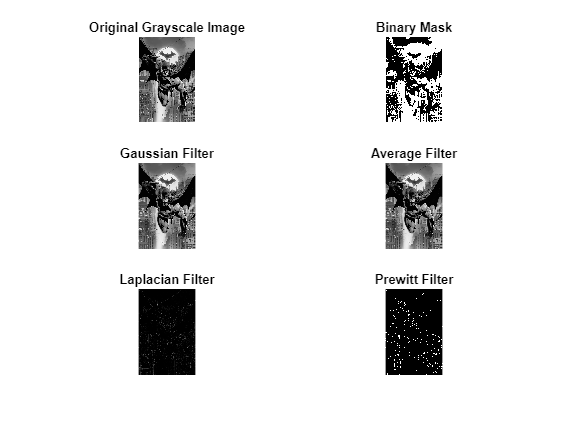

% 1. Load the image
img = imread('Bat.jpg'); % Replace with the correct path to the Batman poster image

% 2. Create a binary mask
gray_img = rgb2gray(img);  % Convert to grayscale
threshold_value = 100;  % Example threshold value, adjust based on your image
binary_mask = imbinarize(gray_img, threshold_value/255);  % Create binary mask

% 3. Apply Low-pass Filters
% Gaussian filter
h_gaussian = fspecial('gaussian', [5,5], 2);  % Gaussian filter with size 5x5 and sigma 2
img_gaussian = imfilter(gray_img, h_gaussian);

% Average filter
h_average = fspecial('average', [5,5]);  % Average filter with size 5x5
img_avg = imfilter(gray_img, h_average);

% 4. Apply High-pass Filters
% Laplacian filter
h_laplacian = fspecial('laplacian', 0.2);  % Laplacian filter
img_laplacian = imfilter(gray_img, h_laplacian);

% Prewitt filter (edge detection)
img_prewitt = edge(gray_img, 'prewitt');

% 5. Display the original, binary mask, and filtered images
figure;
subplot(3,2,1), imshow(gray_img), title('Original Grayscale Image');
subplot(3,2,2), imshow(binary_mask), title('Binary Mask');
subplot(3,2,3), imshow(img_gaussian), title('Gaussian Filter');
subplot(3,2,4), imshow(img_avg), title('Average Filter');
subplot(3,2,5), imshow(img_laplacian), title('Laplacian Filter');
subplot(3,2,6), imshow(img_prewitt), title('Prewitt Filter');

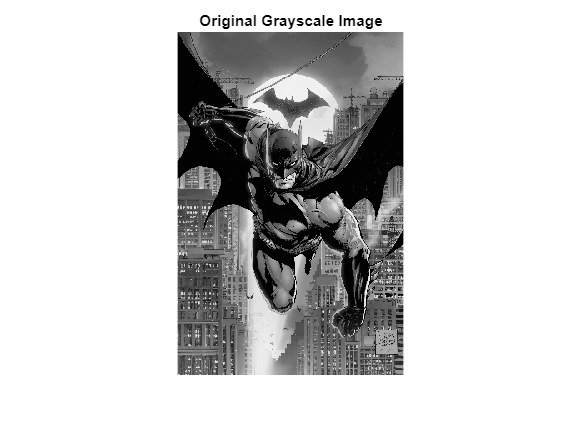


figure, imshow(gray_img); title('Original Grayscale Image');

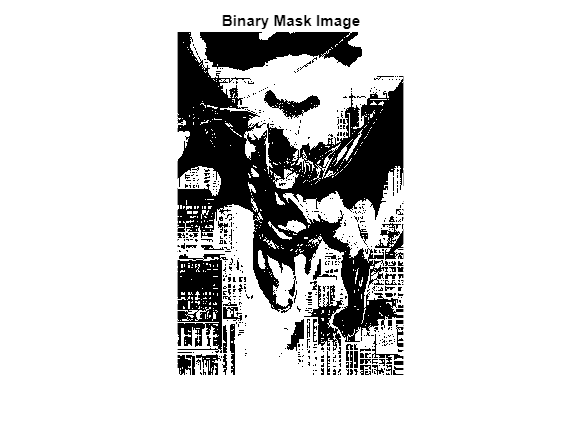

figure, imshow(binary_mask); title('Binary Mask Image');

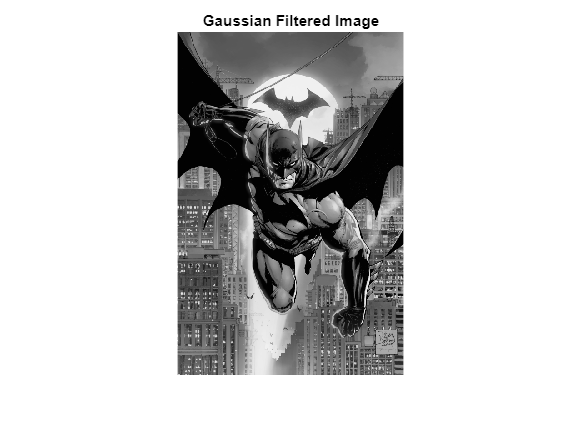

figure, imshow(img_gaussian); title('Gaussian Filtered Image');

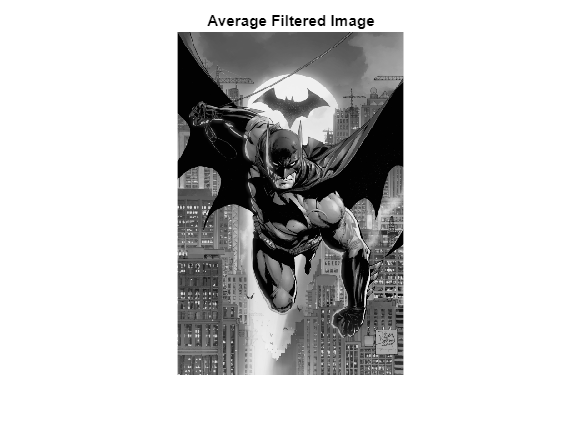

figure, imshow(img_avg); title('Average Filtered Image');

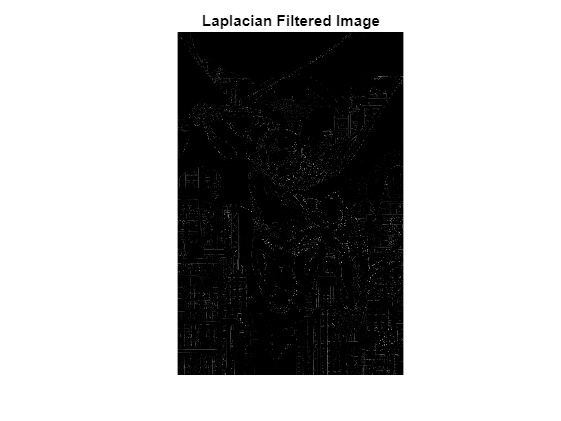

figure, imshow(img_laplacian); title('Laplacian Filtered Image');

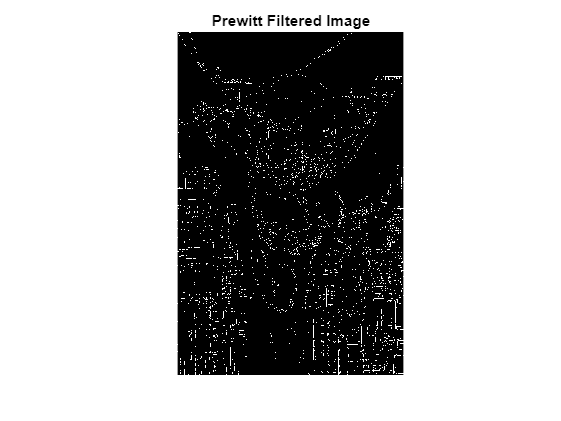

figure, imshow(img_prewitt); title('Prewitt Filtered Image');

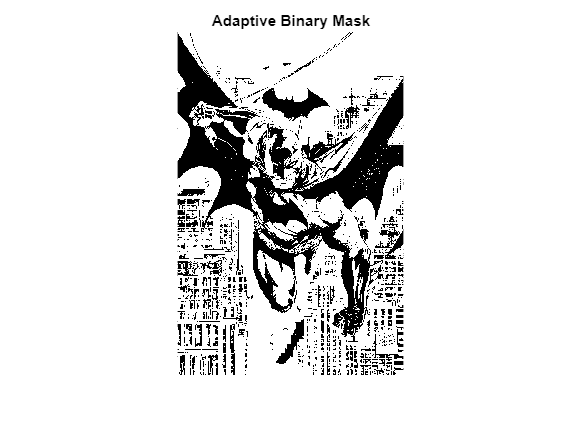



gray_img = rgb2gray(img); 
adaptive_mask = imbinarize(gray_img, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);
figure;
imshow(adaptive_mask);
title('Adaptive Binary Mask');



% Display variable values
disp('Displaying variable values:');

Displaying variable values:


threshold_value:


   100



binary_mask:


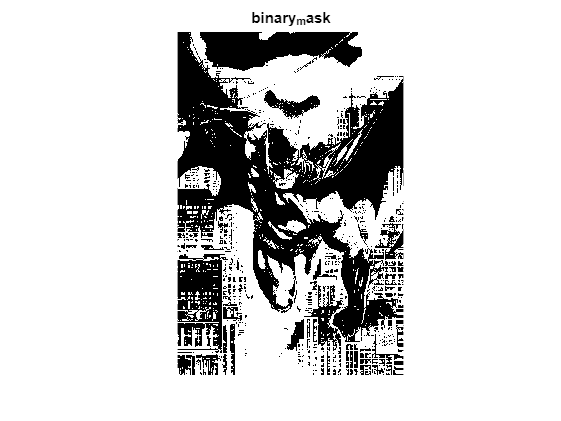

gray_img:


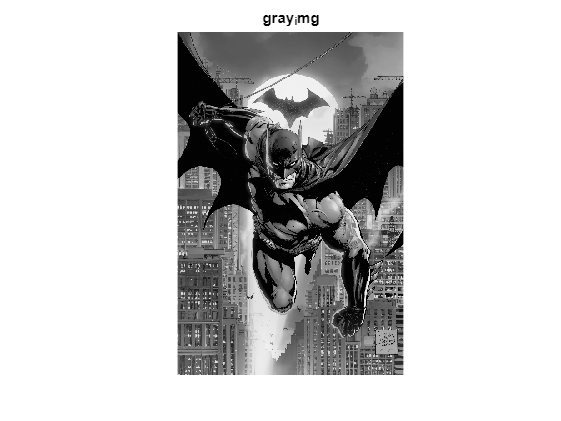

img:


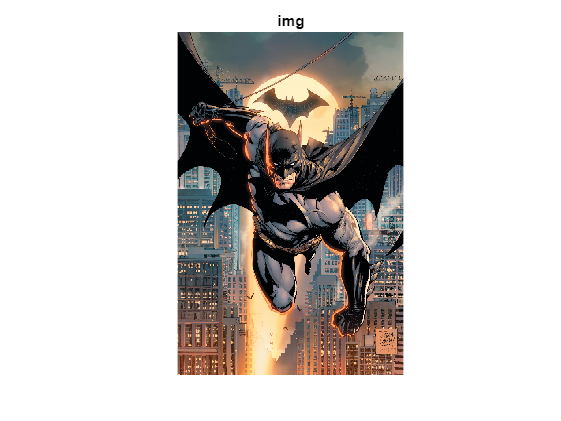

img_gaussian:


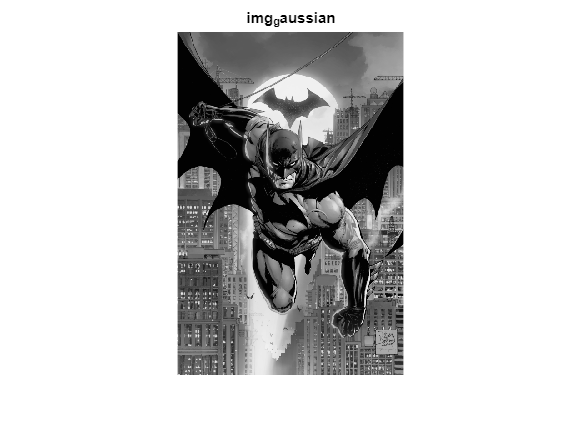

img_avg:


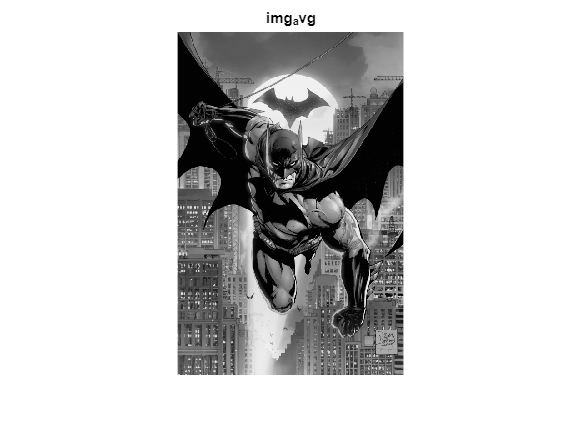

img_laplacian:


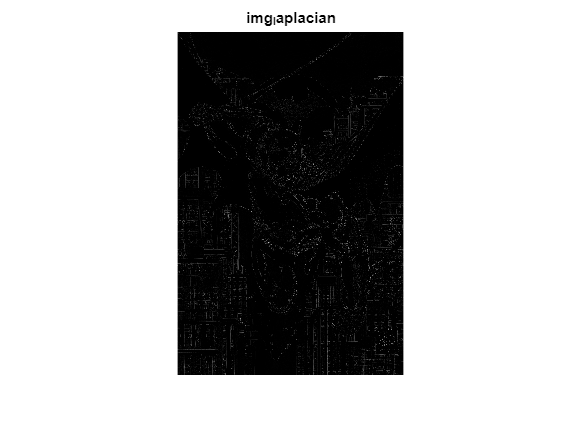

img_prewitt:


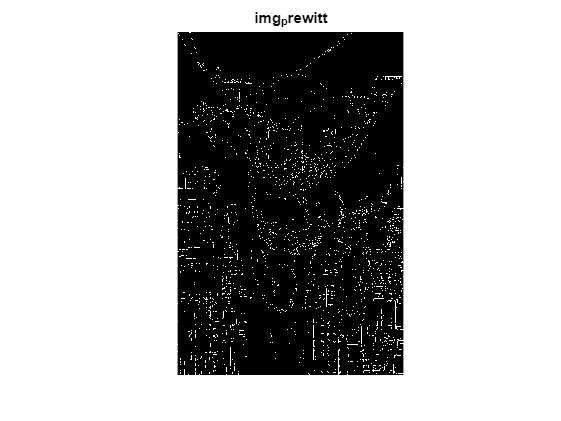

vars = {'threshold_value', 'binary_mask', 'gray_img', 'img', 'img_gaussian', 'img_avg', 'img_laplacian', 'img_prewitt'};
for idx = 1:length(vars)
    disp([vars{idx}, ':']);
    if isequal(vars{idx}, 'threshold_value')
        disp(eval(vars{idx}));
    else
        figure;
        if contains(vars{idx}, 'img') && ~contains(vars{idx}, 'binary_mask')
            imshow(eval(vars{idx}));
        elseif contains(vars{idx}, 'binary_mask')
            imshow(eval(vars{idx}), []);
        else
            imagesc(eval(vars{idx}));
            colorbar;
        end
        title(vars{idx});
    end
end